# Pricing parameters

S0=1;
K=1;
r=0.03;
T0 = datenum(['15-Feb-20' ...
    '08']);
TTM=1.00; 
sigma=0.20;
flag=1;          % flag:  1 call, -1 put

## Quantity of interest

B=exp(-r*TTM); % Discount

## Pricing

exercise a)

F0=S0/B;     % Forward in B&S Model

%TBM: Modify with a cicle
pricingMode = 1; % 1 ClosedFormula, 2 CRR, 3 Monte Carlo
M=100; % M = simulations for MC, steps for CRR;
OptionPrice = EuropeanOptionPrice(F0,K,B,TTM,sigma,pricingMode,M,flag)

OptionPrice = 0.0941

## Errors Rescaling

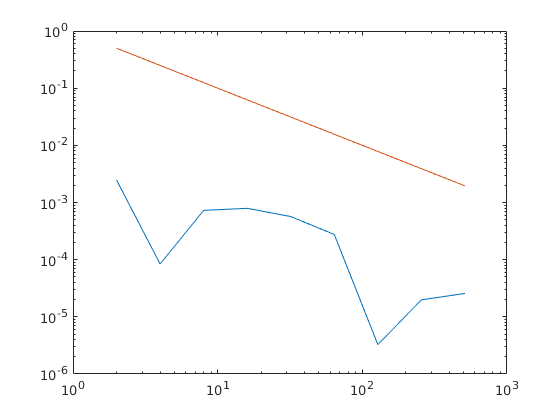

% plot Errors for CRR varing number of steps
[nCRR,errCRR]=PlotErrorCRR(F0,K,B,TTM,sigma);

[r,m,b] = regression(log(nCRR),log(errCRR));
fprintf("slope estimate : %.15g",m);

slope estimate : -0.829081155112086

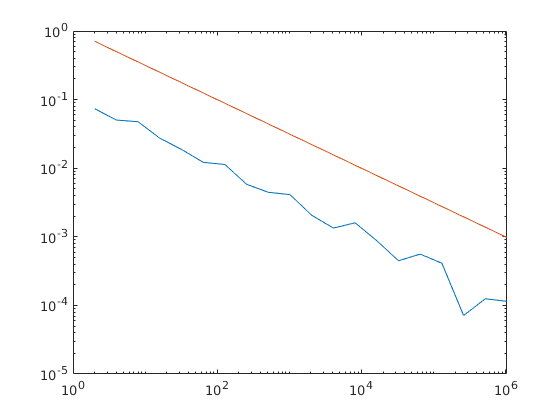


% plot Errors for MC varing number of simulations N 
[nMC,stdEstim]=PlotErrorMC(F0,K,B,TTM,sigma); 

[r,m,b] = regression(log(nMC),log(stdEstim));
fprintf("slope estimate : %.15g",m);

slope estimate : -0.5141268763048

## Plot Delta and Vega for a Call Option with Black&Scholes model

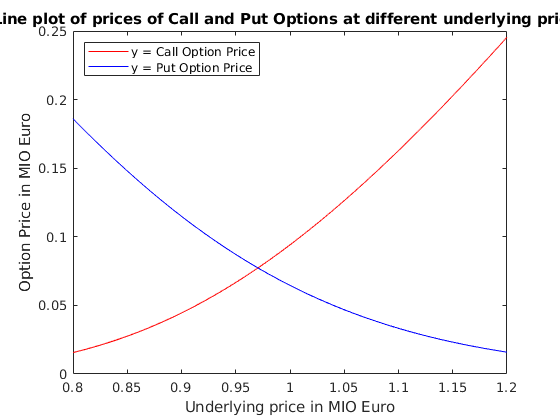

S0=1;
K=1;
r=0.03;
T0 = datenum('15-Feb-2008');
TTM=1.00; 
sigma=0.20;
flag=1; 
%TBM: Set the interval of interest for S 

S0 = [0.8:0.01:1.2];
F0 = S0/B;     % Forward in B&S Model

% delta = DeltaBlackScholes(F0,K,B,TTM,sigma,flag)
% vega = VegaBlackScholes(F0,K,B,TTM,sigma,flag)

for i=1:size(S0,2)
    
      OptionPriceCall(i) = EuropeanOptionClosed(F0(i),K,B,TTM,sigma,1);
      OptionPricePut(i) = EuropeanOptionClosed(F0(i),K,B,TTM,sigma,-1);
      deltaCall(i) = DeltaBlackScholes(F0(i),K,B,TTM,sigma,1);
      deltaPut(i) = DeltaBlackScholes(F0(i),K,B,TTM,sigma,-1);
      vega(i) = VegaBlackScholes(F0(i),K,B,TTM,sigma,flag);
end

%TBM: plot price, Delta and Vega

% Plot of Option Prices
figure(1);
plot(S0,OptionPriceCall,'-r',S0,OptionPricePut,'-b',S0,0,'k');
title('Line plot of prices of Call and Put Options at different underlying prices');
xlabel('Underlying price in MIO Euro');
ylabel('Option Price in MIO Euro');
legend({'y = Call Option Price','y = Put Option Price'},'Location','northwest');

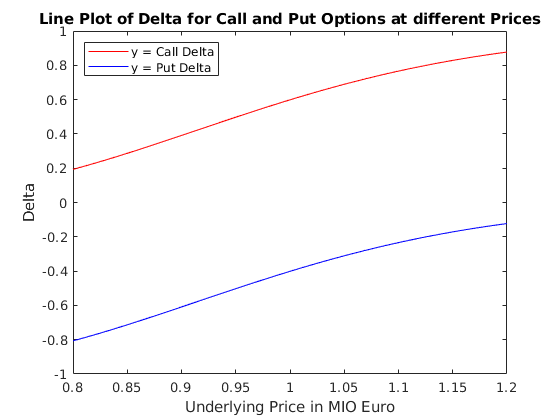


%Plot of Deltas
figure(2);
plot(S0,deltaCall,'-r',S0,deltaPut,'-b',S0,0,'k');
title('Line Plot of Delta for Call and Put Options at different Prices');
xlabel('Underlying Price in MIO Euro');
ylabel('Delta');
legend({'y = Call Delta','y = Put Delta'},'Location','northwest');

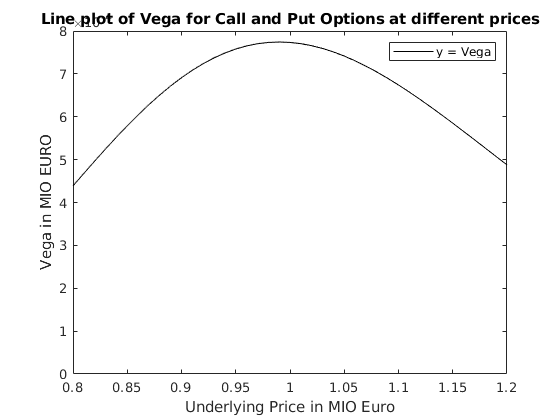


%Plot of Vega
figure(3);
plot(S0,vega,'-k',S0,0,'--k');
title('Line plot of Vega for Call and Put Options at different prices')
xlabel('Underlying Price in MIO Euro');
ylabel('Vega in MIO EURO');
legend({'y = Vega'},'Location','northeast');